%Created by Juan Briones
%Student number A00825852

%Inputs - x and y vectors

x=[10 15 20 22.5];
y=[227.04 362.78 517.35 602.97];
order= 3;
vel = 16;

%Process - Use the corresponding regression formulas for
%the direct interpolation
%sortedArray = sort(abs(x-vel))

%idx = zeros(1, length(x))
%for i=1:length(x) 
%    idx(1, i) =  find(x==(sortedArray(i)+vel))
%end

A = [];
for i=1:length(x)
    %A(i, 1) = 1;
    for j=1:length(x)
        %A(i, j+1) = x(i)^j;
        A(i, j) = x(i)^(j-1);
    end
end

B = [];
for i=1:length(y)
    B(i,1) = y(i);
end
% B = y'

R = inv(A)*B;
a0 = R(1,1)

a0 = -4.2540

a1 = R(2,1)

a1 = 21.2655

a2 = R(3,1)

a2 = 0.1320

a3 = R(4,1)

a3 = 0.0054


f = @(x) a0 + a1*x + a2*power(x, 2) + a3*power(x,3);

result = f(16)

result = 392.0572

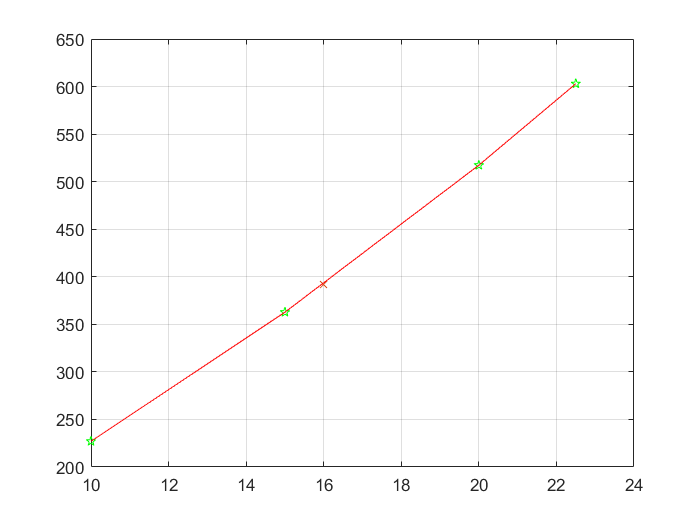



% GRAPH
figure
plot(x, y, 'pg')
hold on
plot(16, result, 'X')
hold on
plot(x, f(x), '-r')
hold off
grid


%Output - display results
